Se tiene un grupo de parámetros Denavit-Hartenber, dan como resultado la posición del robot en el espacio.

close all; clear all; clc;
syms t1 %Crea un valor Simbolico de theta1
a1=0;
d1=5; %Distancias en centimetros

alpha1=90;
theta1=t1; %Valor aleatorio ya que modificara la estructura final

%MATRIZ A1
A1=[cosd(theta1), -sind(theta1)*cosd(alpha1), sind(theta1)*sind(alpha1), a1*cosd(theta1);...
    sind(theta1), cosd(theta1)*cosd(alpha1), - cosd(theta1)*sind(alpha1), a1*sind(theta1);...
    0, sind(alpha1), cosd(alpha1), d1;...
    0,0,0,1]

$$A1 = \left(\begin{array}{cccc} \cos\left(\frac{\pi \,t_{1}}{180}\right) & 0 & \sin\left(\frac{\pi \,t_{1}}{180}\right) & 0\\ \sin\left(\frac{\pi \,t_{1}}{180}\right) & 0 & -\cos\left(\frac{\pi \,t_{1}}{180}\right) & 0\\ 0 & 1 & 0 & 5\\ 0 & 0 & 0 & 1 \end{array}\right)$$

%%%
theta1= 65;
A1n=[cosd(theta1), -sind(theta1)*cosd(alpha1), sind(theta1)*sind(alpha1), a1*cosd(theta1);...
    sind(theta1), cosd(theta1)*cosd(alpha1), - cosd(theta1)*sind(alpha1), a1*sind(theta1);...
    0, sind(alpha1), cosd(alpha1), d1;...
    0,0,0,1]

A1n =     0.4226         0    0.9063         0
    0.9063         0   -0.4226         0
         0    1.0000         0    5.0000
         0         0         0    1.0000


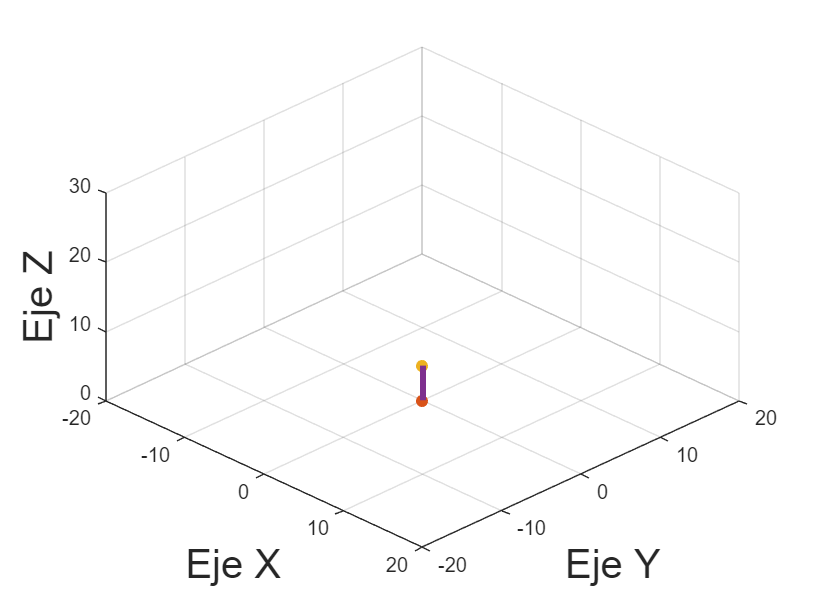


figure
plot3([0, A1n(1,4)], [0,A1n(2,4)], [0,A1n(3,4)])

hold on;
scatter3(0,0,0,"filled")
scatter3(A1n(1,4), A1n(2,4), A1n(3,4),"filled")
plot3([0,A1n(1,4)], [0,A1n(2,4)], [0,A1n(3,4)], "LineWidth",3)
grid on;

xlabel("Eje X", "FontSize", 20)
ylabel("Eje Y", "FontSize", 20)
zlabel("Eje Z", "FontSize", 20)
axis([-20,20,-20,20,0,30])
view(45,45)

syms t2
a2=10;
d2=0; 
alpha2=0;
theta2=t2;


A2=[cosd(theta2), -sind(theta2)*cosd(alpha2), sind(theta2)*sind(alpha2), a2*cosd(theta2);...
    sind(theta2), cosd(theta2)*cosd(alpha2), - cosd(theta2)*sind(alpha2), a2*sind(theta2);...
    0, sind(alpha2), cosd(alpha2), d2;...
    0,0,0,1]

$$A2 = \left(\begin{array}{cccc} \cos\left(\frac{\pi \,t_{2}}{180}\right) & -\sin\left(\frac{\pi \,t_{2}}{180}\right) & 0 & 10\,\cos\left(\frac{\pi \,t_{2}}{180}\right)\\ \sin\left(\frac{\pi \,t_{2}}{180}\right) & \cos\left(\frac{\pi \,t_{2}}{180}\right) & 0 & 10\,\sin\left(\frac{\pi \,t_{2}}{180}\right)\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

theta2=115;
A2n=[cosd(theta2), -sind(theta2)*cosd(alpha2), sind(theta2)*sind(alpha2), a2*cosd(theta2);...
    sind(theta2), cosd(theta2)*cosd(alpha2), - cosd(theta2)*sind(alpha2), a2*sind(theta2);...
    0, sind(alpha2), cosd(alpha2), d2;...
    0,0,0,1]

A2n =    -0.4226   -0.9063         0   -4.2262
    0.9063   -0.4226         0    9.0631
         0         0    1.0000         0
         0         0         0    1.0000


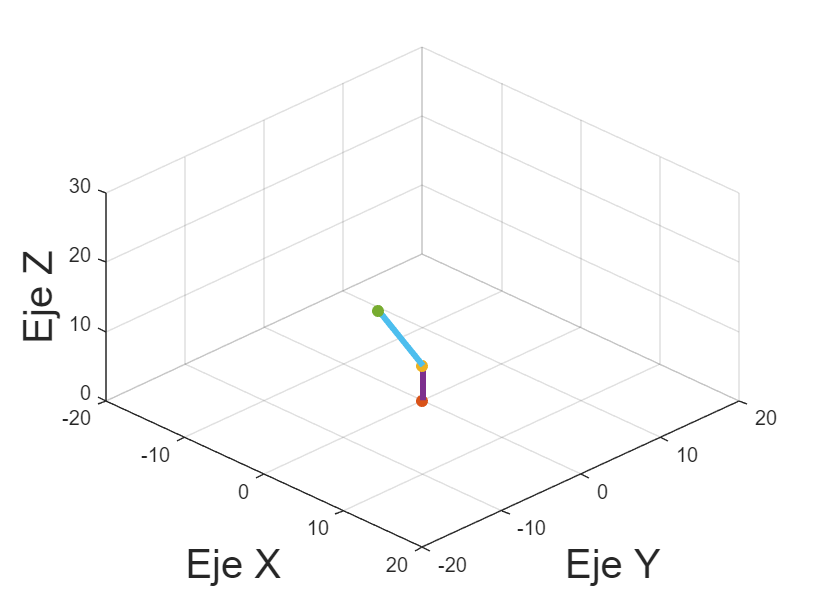

AC2=A1*A2;
AC2n=A1n* A2n; %la n representa numerico
scatter3(AC2n(1,4), AC2n(2,4), AC2n(3,4), "filled")
plot3([A1n(1,4), AC2n(1,4)], [A1n(2,4),AC2n(2,4)], [A1n(3,4), AC2n(3,4)], "LineWidth",3)

syms t3
a3=10;
d3=0; 
alpha3=0;
theta3=t2;


A3=[cosd(theta3), -sind(theta3)*cosd(alpha3), sind(theta3)*sind(alpha3), a3*cosd(theta3);...
    sind(theta3), cosd(theta3)*cosd(alpha3), - cosd(theta3)*sind(alpha3), a3*sind(theta3);...
    0, sind(alpha3), cosd(alpha3), d3;...
    0,0,0,1]

$$A3 = \left(\begin{array}{cccc} \cos\left(\frac{\pi \,t_{2}}{180}\right) & -\sin\left(\frac{\pi \,t_{2}}{180}\right) & 0 & 10\,\cos\left(\frac{\pi \,t_{2}}{180}\right)\\ \sin\left(\frac{\pi \,t_{2}}{180}\right) & \cos\left(\frac{\pi \,t_{2}}{180}\right) & 0 & 10\,\sin\left(\frac{\pi \,t_{2}}{180}\right)\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

theta3=315;
A3n=[cosd(theta3), -sind(theta3)*cosd(alpha3), sind(theta3)*sind(alpha3), a2*cosd(theta3);...
    sind(theta3), cosd(theta3)*cosd(alpha3), - cosd(theta3)*sind(alpha3), a2*sind(theta3);...
    0, sind(alpha3), cosd(alpha3), d3;...
    0,0,0,1]

A3n =     0.7071    0.7071         0    7.0711
   -0.7071    0.7071         0   -7.0711
         0         0    1.0000         0
         0         0         0    1.0000


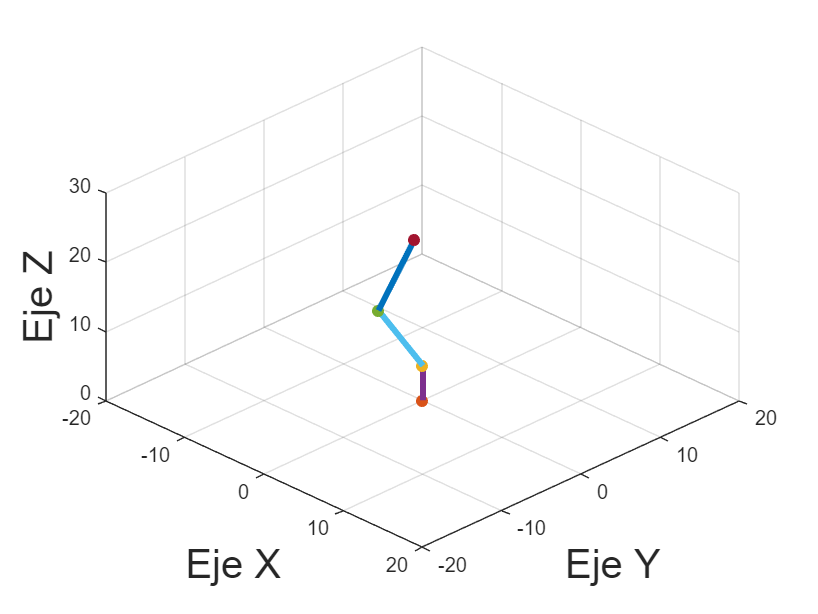

AC3=A1*A2*A3n;
AC3n=A1n* A2n *A3n; %la n representa numerico
scatter3(AC3n(1,4), AC3n(2,4), AC3n(3,4), "filled")
plot3([AC2n(1,4), AC3n(1,4)], [AC2n(2,4),AC3n(2,4)], [AC2n(3,4), AC3n(3,4)], "LineWidth",3)